% B11102112 李家睿

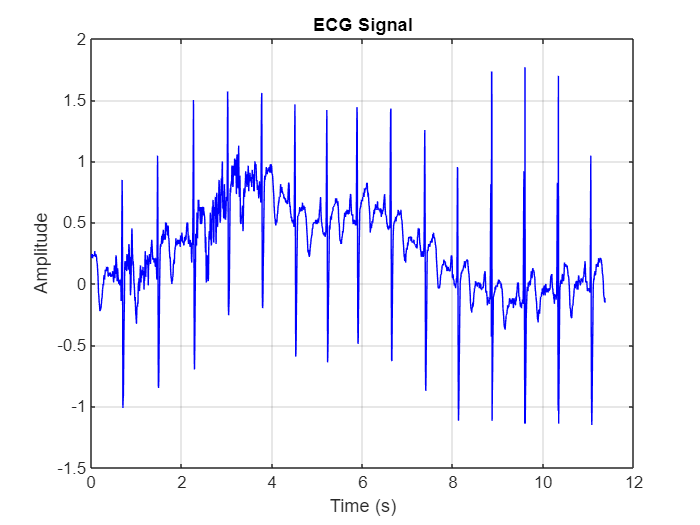

% Clear workspace and command window
clear; clc;

% (1) Load ECG signal from .mat file
load('wecg.mat');  

% Sampling info
fs = 180;                     % Sampling frequency in Hz
Ts = 1/fs;                    % Sampling time interval
t = (0:length(wecg)-1) * Ts;            % Time vector (same length as wecg)

% Eliminate DC offset 
dc_offset = mean(wecg(wecg<0));
wecg = wecg - dc_offset;

% (a) Plot ECG signal
figure;
plot(t, wecg, 'b');
xlabel('Time (s)');
ylabel('Amplitude');
title('ECG Signal');
grid on;

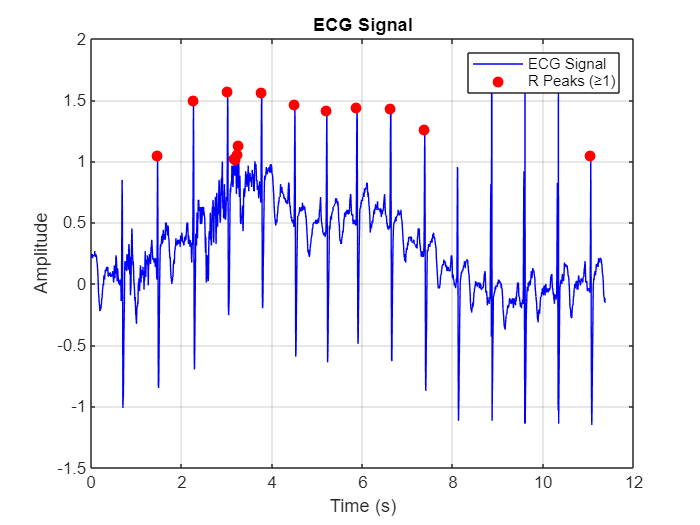


% (b) Find R peaks (peaks >= 1)
[peaks, locs] = findpeaks(wecg, 'MinPeakHeight', 1);

% Plot R peaks on ECG signal
figure;
plot(t, wecg, 'b');
xlabel('Time (s)');
ylabel('Amplitude');
title('ECG Signal');
hold on;
plot(t(locs), peaks, 'ro', 'MarkerFaceColor', 'r');
legend('ECG Signal', 'R Peaks (≥1)');
grid on;

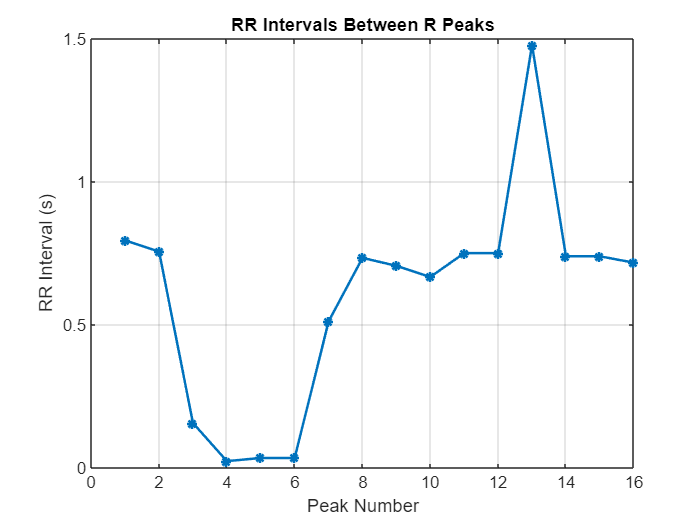



% (c) Calculate RR intervals (in seconds)
RR_intervals = diff(locs) * Ts;

% Plot RR intervals
figure;
plot(RR_intervals, '-*', 'LineWidth', 1.5);
xlabel('Peak Number');
ylabel('RR Interval (s)');
title('RR Intervals Between R Peaks');
grid on;

%Today's lab is easier than last week's lab, 
% but I’m very worried about next week’s midterm exam 
% because I’m still not very familiar with all the syntax. 